% plot is easy


# plot func is the most basic visulable func

## 当**plot**接受两个行向量时

plot(x, y)

建立了$f:|x_i \to y_{i\;}$

的作图

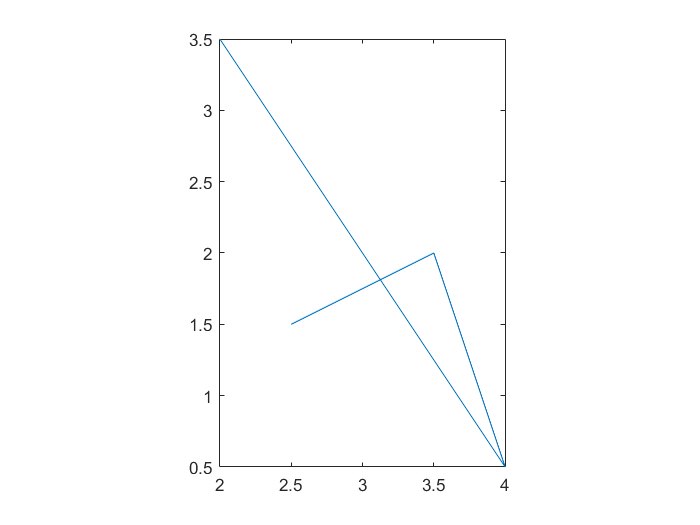

x=[2.5 3.5 4 2];
y=[1.5 2 0.5 3.5];

plot(x, y);
axis equal;
axis([2 4 0.5 3.5])

## 当**plot**接受一个行向量时

plot(x)

便等价于

plot(1:length(x), x)

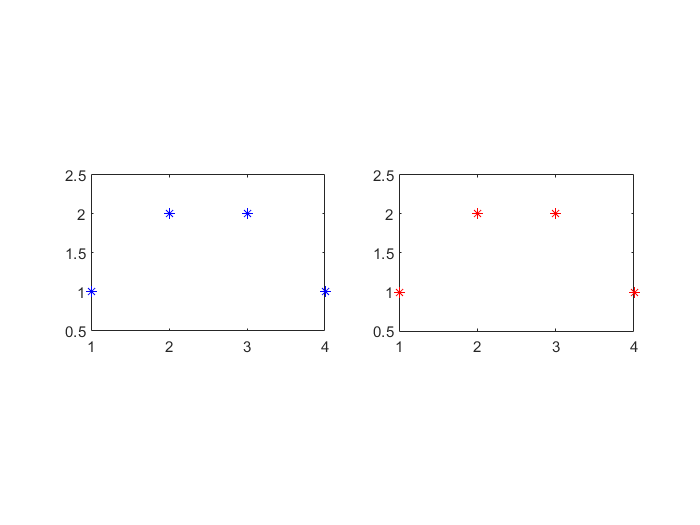

subplot(1, 2, 1);
single_vector=[1 2 2 1];
plot(single_vector, 'b*');
axis equal
axis([1 4 0.5 2.5])

subplot(1, 2, 2);
plot(1:length(single_vector), single_vector, 'r*');
axis equal
axis([1 4 0.5 2.5])

## 当**plot**接受一组复数域上的向量时

plot(cp)

相当于

plot(real(cp), img(cp))

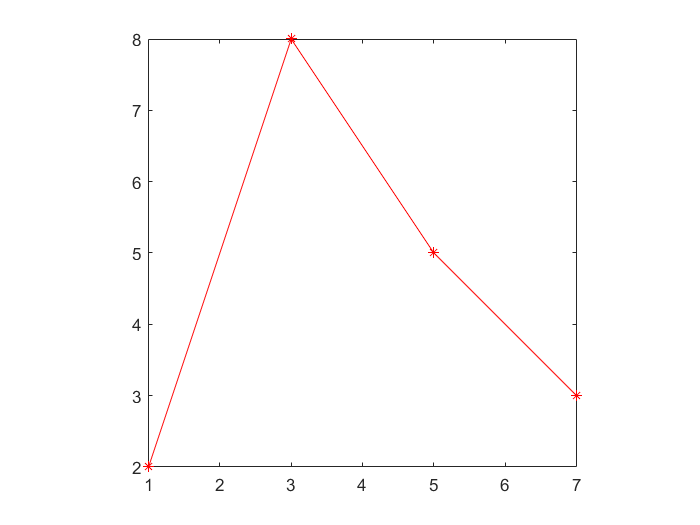

figure(2);
real_part=1:2:7;
img_part=[2 8 5 3];
plot(complex(real_part, img_part), 'r-*');
axis square

## 当**plot**接受一个向量与一个矩阵时

plot(x, mat)

若mat行数等于length(x)，则以列向量为纵坐标绘图

若mat列数等于length(x)，则以其行向量为纵坐标绘图

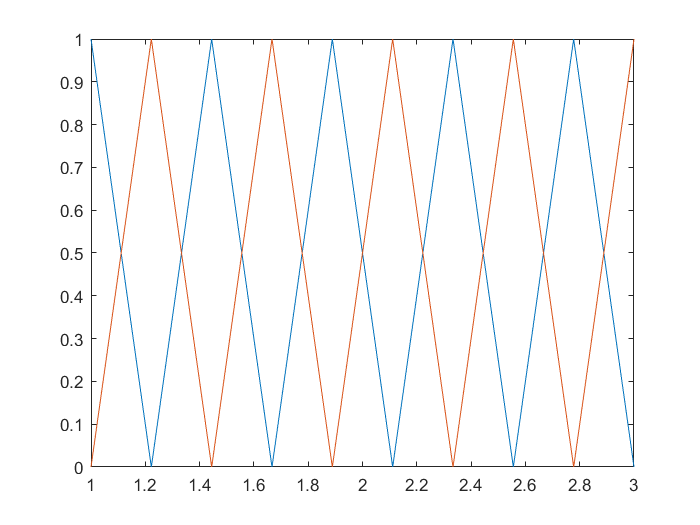

x = linspace(1, 3, 10);
y = [eye(2) eye(2) eye(2) eye(2) eye(2)];

plot(x, y);

x = linspace(1, 4, 3);
y = eye(3);
y(:, 1) = ones(3, 1);
disp(y);

     1     0     0
     1     1     0
     1     0     1



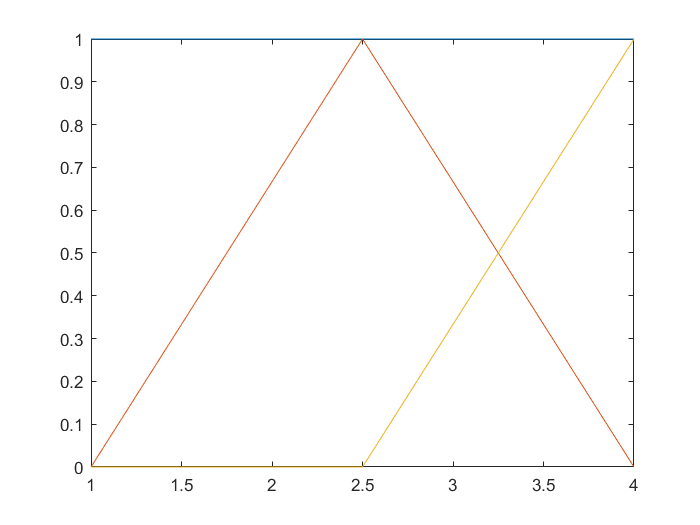


plot(x, y);

可见，若mat为方阵，则优先以列向量表示

**plot(mat1, mat2)**

**当x, y 同型时，以x, y对应列元素为横纵坐标绘制曲线**

x = [2 3 4; 1 9 2; 1 2 3];
y = [4 3 2; 2 4 1; 2 1 4];
disp('x is:');

x is:



disp(x);

     2     3     4
     1     9     2
     1     2     3




disp('y is:');

y is:


disp(y);

     4     3     2
     2     4     1
     2     1     4



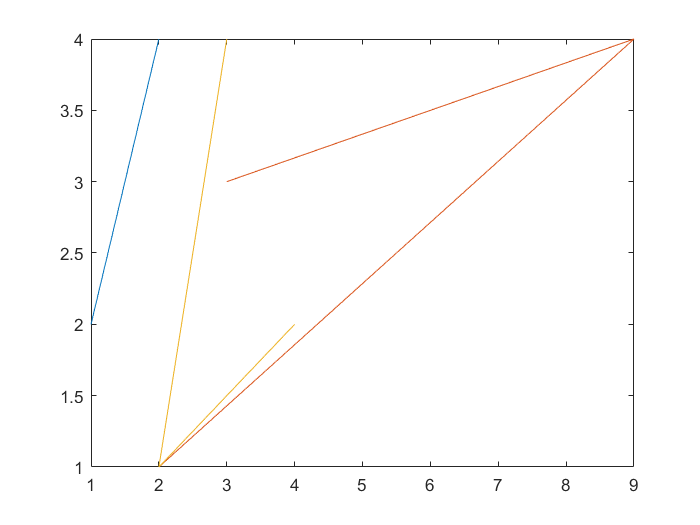

plot(x,y);

## 当plot接受向量对时

plot(x1, y1, x2, y2, ...)

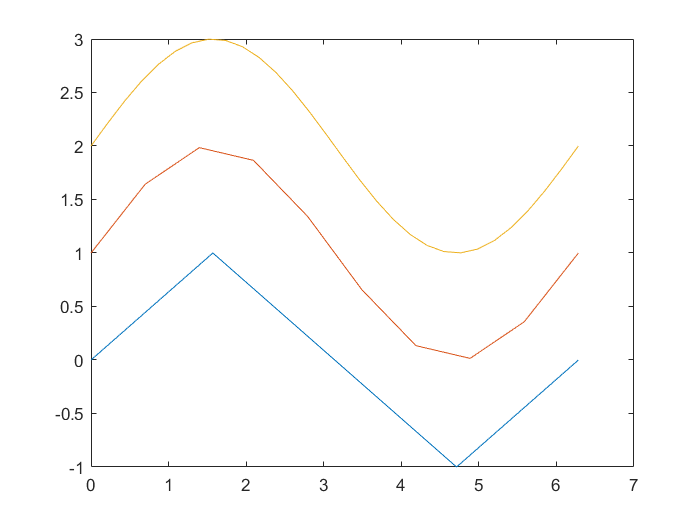

t1=linspace(0, 2, 5)'*pi; 
t2=linspace(0, 2, 10)' *pi;
t3=linspace(0, 2, 30)'*pi;
plot(t1, sin(t1), t2, sin(t2)+1, t3, sin(t3)+2);

# Other Choices

'_' 实线

‘:' 虚线

’-.' 点画线

'--' 双画线

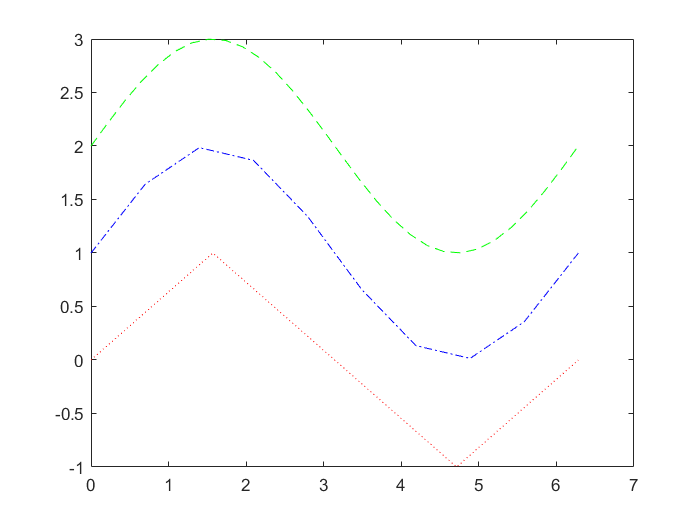

t1=linspace(0, 2, 5)'*pi; 
t2=linspace(0, 2, 10)' *pi;
t3=linspace(0, 2, 30)'*pi;
plot(t1, sin(t1), 'r:', t2, sin(t2)+1, 'b-.', t3, sin(t3)+2, 'g--');

red 

green blue

white 

k black

"*"

"o"

# fplot

Let's see a bad example first

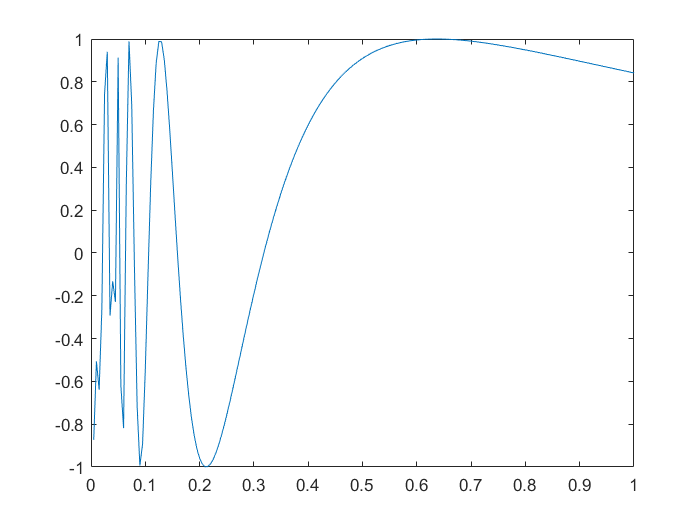

x = 0:0.005:1;
y = sin(1./x);
plot(x,y);

The plot can not describe$f\left(x\right)=\mathrm{sin}\left(\frac{1}{x}\right)$correctly

So we need to use fplot func

fplot(f, lims, choices)

f is func, often we use func handle to pass.

lims is the limit, use [xmin, xmax] to d

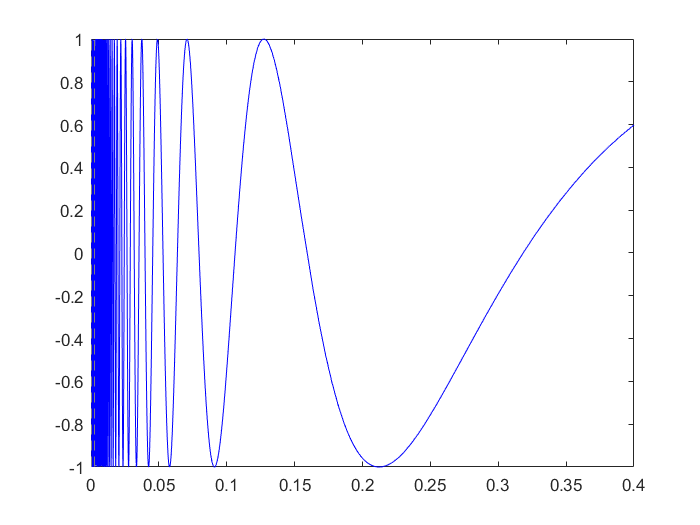

% Now let's plot f(x)=1/x again.

fplot(@(x) sin(1./x), [0, 0.4], 'b')

如果以参数方程给出，则fplot调用格式为

fplot(funcx, funcy, tlims, choices)

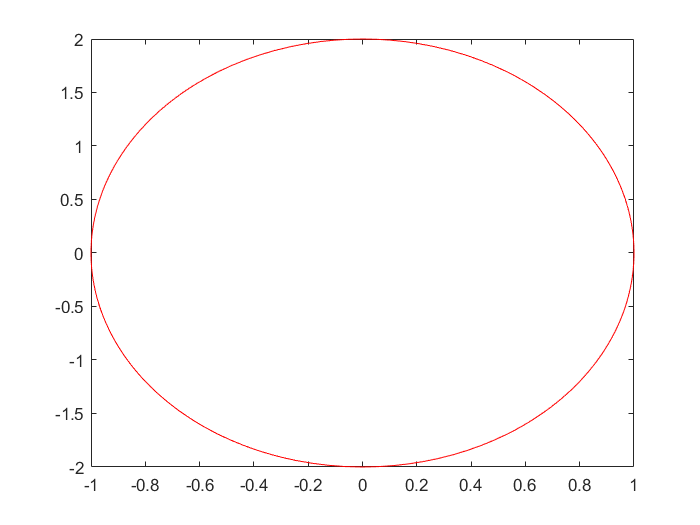

fplot(@(t) sin(t), @(t) 2*cos(t), [0, 2*pi], 'r')

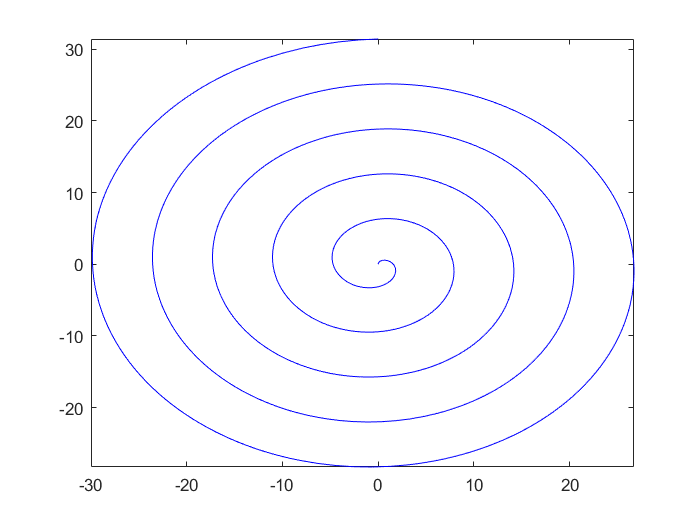

fplot(@(t) t.*sin(t), @(t) t.*cos(t), [0, 10*pi], 'b')